clear; close all; clc

% Training set
trainFD001 = readmatrix('train_FD001.txt');
trainFD002 = readmatrix('train_FD002.txt');
trainFD003 = readmatrix('train_FD003.txt');
trainFD004 = readmatrix('train_FD004.txt');

% Test set
testFD001 = readmatrix('test_FD001.txt');
testFD002 = readmatrix('test_FD002.txt');
testFD003 = readmatrix('test_FD003.txt');
testFD004 = readmatrix('test_FD004.txt');

% RUL (Remaining Useful Life)
RUL_FD001 = readmatrix('RUL_FD001.txt');
RUL_FD002 = readmatrix('RUL_FD002.txt');
RUL_FD003 = readmatrix('RUL_FD003.txt');
RUL_FD004 = readmatrix('RUL_FD004.txt');

% import dataset

% extract predictors and variables
[X_train, unit_train, cycle_train] = extractPredictors(trainFD001);

Matrice X: 20631 osservazioni (righe) × 24 variabili (colonne)



% visualize first 5 observation
disp('first five observation of matrix X_train:');

first five observation of matrix X_train:


disp(X_train(1:5,:));

   1.0e+03 *

   -0.0000   -0.0000    0.1000    0.5187    0.6418    1.5897    1.4006    0.0146    0.0216    0.5544    2.3881    9.0462    0.0013    0.0475    0.5217    2.3880    8.1386    0.0084    0.0000    0.3920    2.3880    0.1000    0.0391    0.0234
    0.0000   -0.0000    0.1000    0.5187    0.6421    1.5918    1.4031    0.0146    0.0216    0.5537    2.3880    9.0441    0.0013    0.0475    0.5223    2.3881    8.1315    0.0084    0.0000    0.3920    2.3880    0.1000    0.0390    0.0234
   -0.0000    0.0000    0.1000    0.5187    0.6423    1.5880    1.4042    0.0146    0.0216    0.5543    2.3881    9.0529    0.0013    0.0473    0.5224    2.3880    8.1332    0.0084    0.0000    0.3900    2.3880    0.1000    0.0390    0.0233
    0.0000         0    0.1000    0.5187    0.6423    1.5828    1.4019    0.0146    0.0216    0.5544    2.3881    9.0495    0.0013    0.0471    0.5229    2.3881    8.1338    0.0084    0.0000    0.3920    2.3880    0.1000    0.0389    0.0234
   -0.0000   -0.0000  

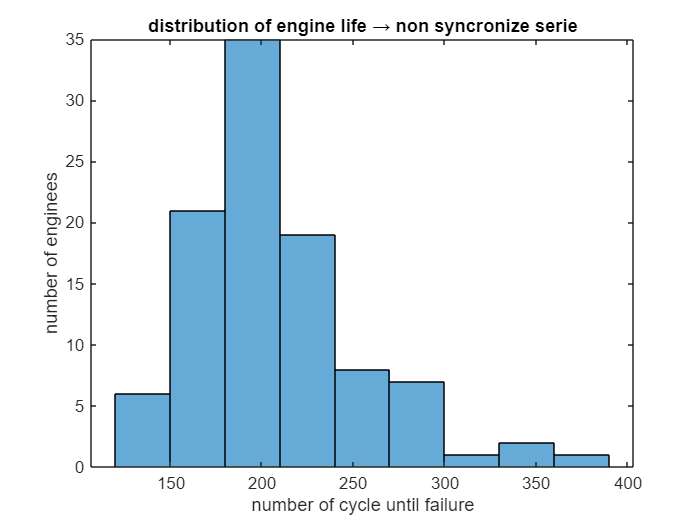


% ---- 1. check non syncronize temporal series ----
uniqueUnits = unique(unit_train);
nUnits = numel(uniqueUnits);
cyclesPerUnit = zeros(nUnits,1);

for i = 1:nUnits
    cyclesPerUnit(i) = sum(unit_train==uniqueUnits(i));
end

figure;
histogram(cyclesPerUnit);
xlabel('number of cycle until failure');
ylabel('number of enginees');
title('distribution of engine life → non syncronize serie');


fprintf('number of engine: %d\n', nUnits);

number of engine: 100


fprintf('average engine life (cycles): %.2f\n', mean(cyclesPerUnit));

average engine life (cycles): 206.31



% ---- 2. check missing values ----
nMissing = sum(isnan(X_train),1);
missingVars = find(nMissing>0);

if ~isempty(missingVars)
    fprintf('variables with missed values:\n');
    disp(missingVars);
else
    fprintf('No missing values.\n');
end

No missing values.



% ---- 3.constant variables----
varPerCol = var(X_train);
constVars = find(varPerCol==0);

if ~isempty(constVars)
    fprintf('constant variables:\n');
    disp(constVars);
else
    fprintf('no constant variable.\n');
end

constant variables:


     3    21    22



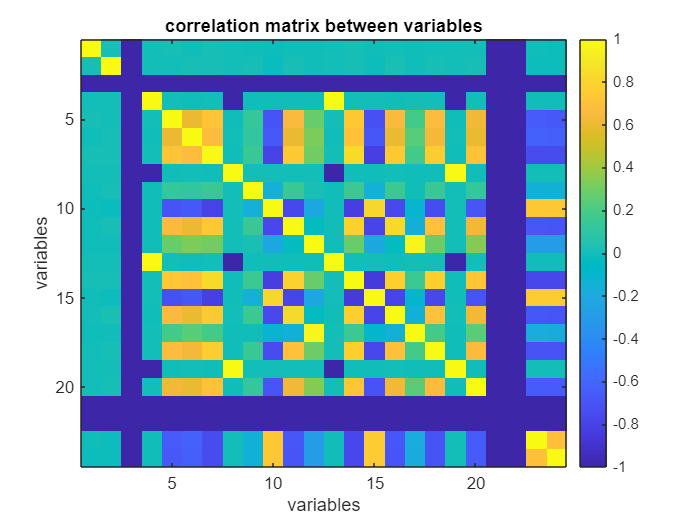


% ---- 4.correlation ----
corrMatrix = corr(X_train);
figure;
imagesc(corrMatrix);
colorbar;
title('correlation matrix between variables');
xlabel('variables');
ylabel('variables');

 Analysis dataset: train_FD001.txt


Matrice X: 20631 osservazioni (righe) × 24 variabili (colonne)


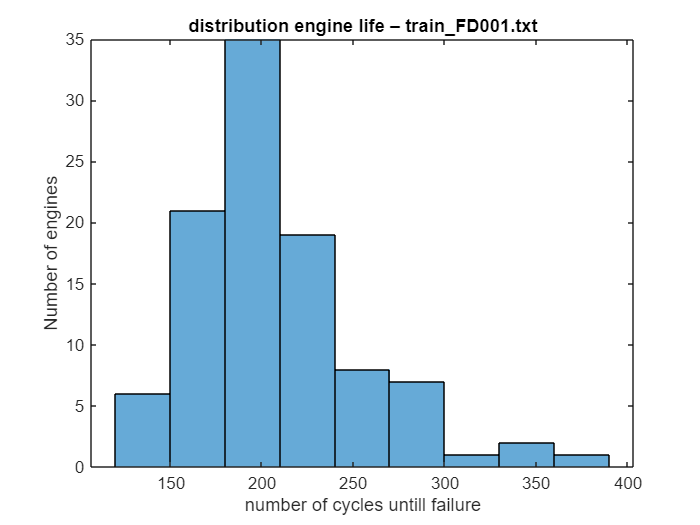

number of eninges: 100


average engine life (cycles): 206.31


no missin values.


constant variables:


     3    21    22



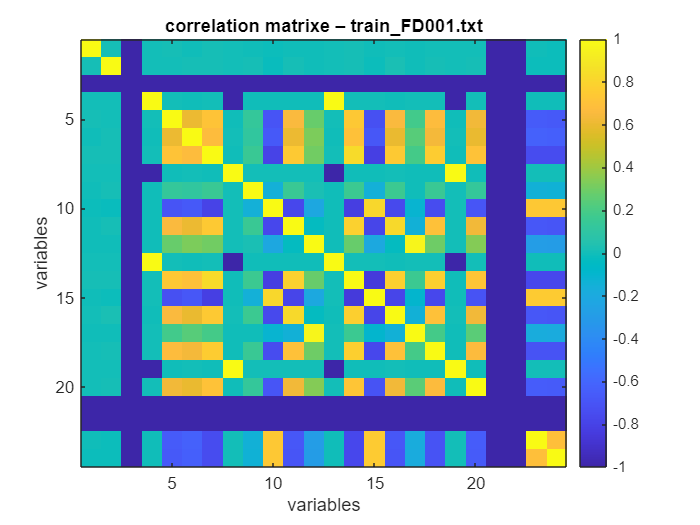

Variance explained by first 10 PCs:


   53.0980   12.3458    5.9549    5.8363    5.6593    2.4338    2.1659    2.0489    1.8002    1.7045



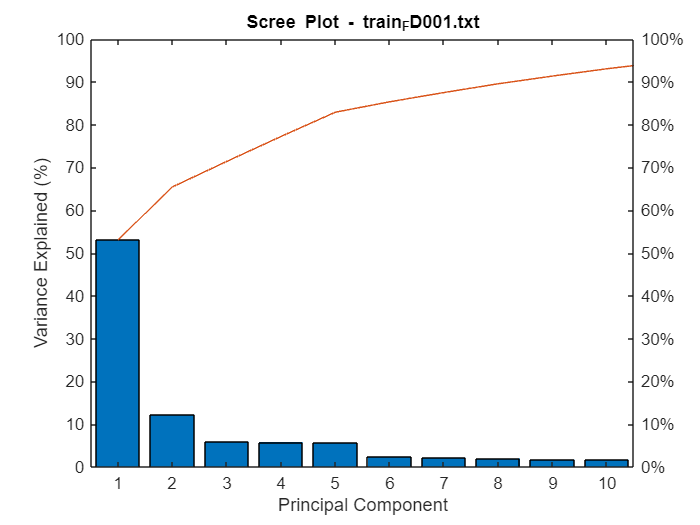

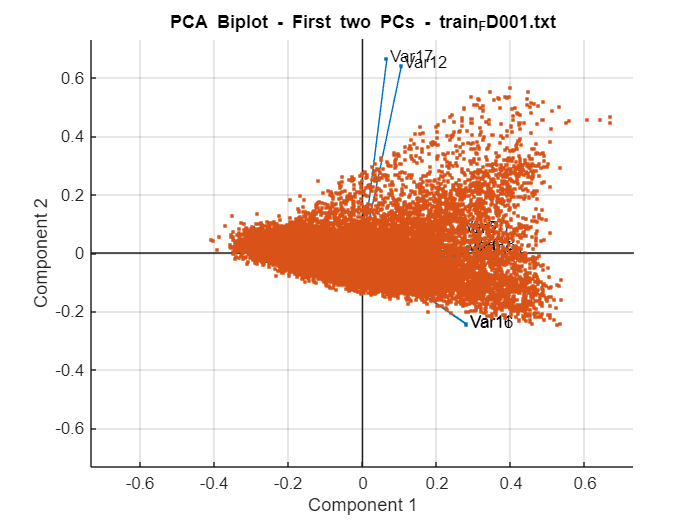

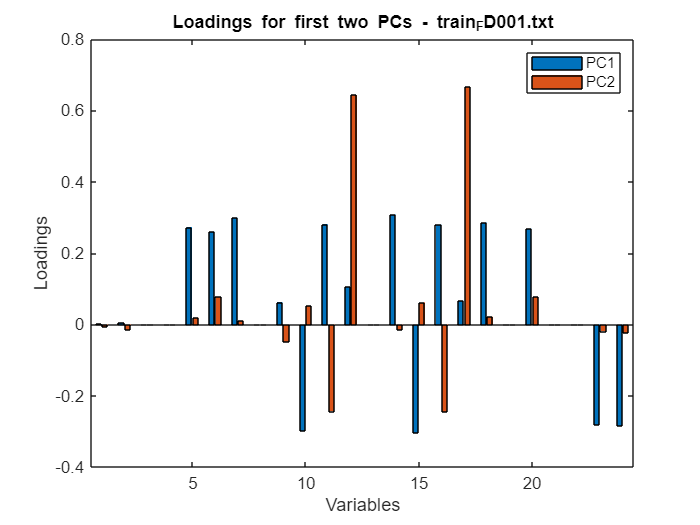

 Analysis dataset: train_FD002.txt


Matrice X: 53759 osservazioni (righe) × 24 variabili (colonne)


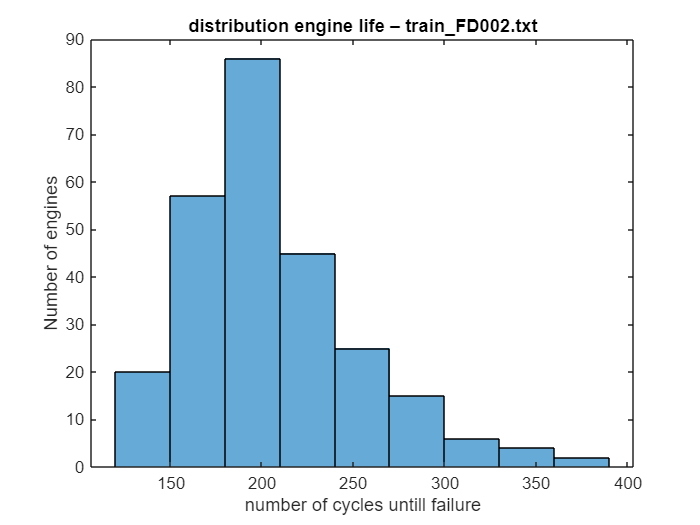

number of eninges: 260


average engine life (cycles): 206.77


no missin values.


no constant variables.


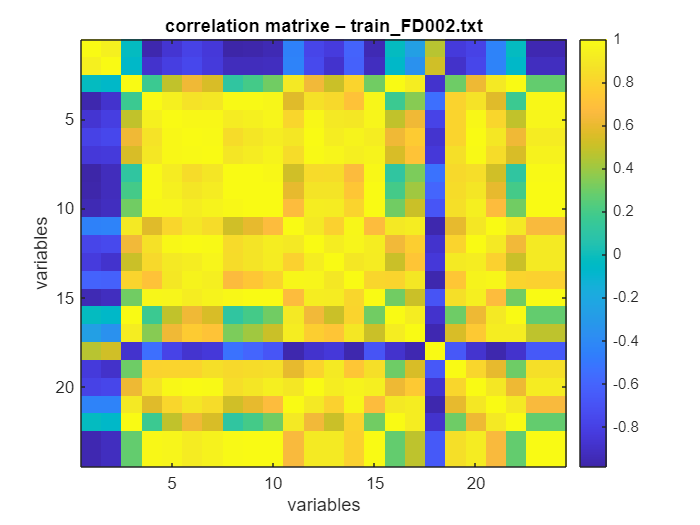

Variance explained by first 10 PCs:


   77.3471   19.9607    1.9075    0.4085    0.1682    0.0960    0.0677    0.0255    0.0056    0.0047



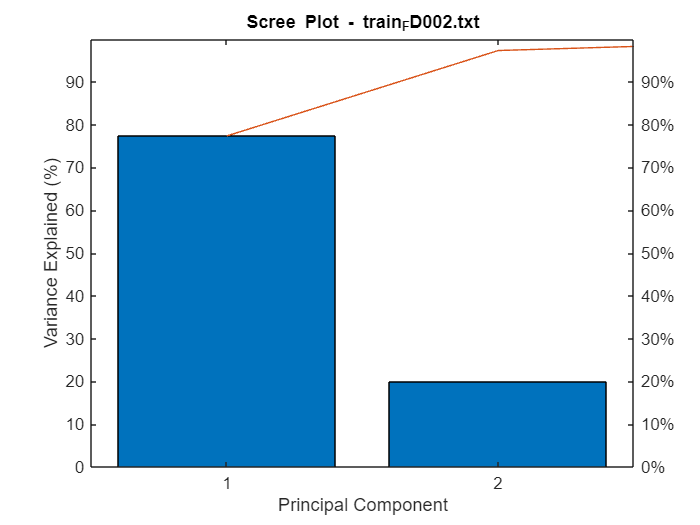

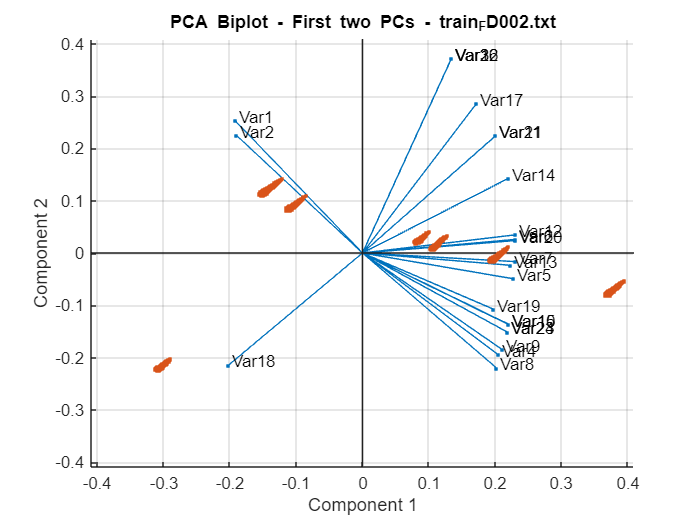

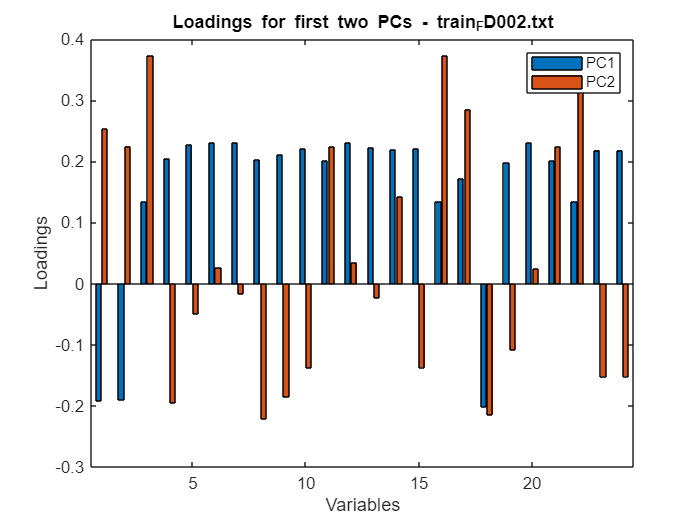

 Analysis dataset: train_FD003.txt


Matrice X: 24720 osservazioni (righe) × 24 variabili (colonne)


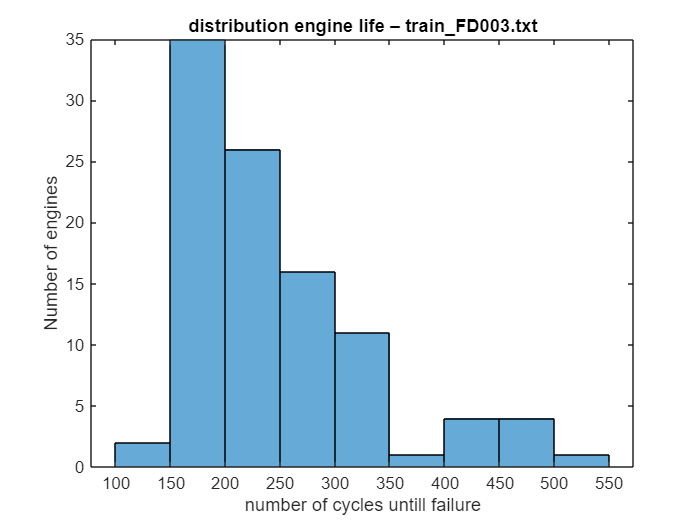

number of eninges: 100


average engine life (cycles): 247.20


no missin values.


constant variables:


     3    21    22



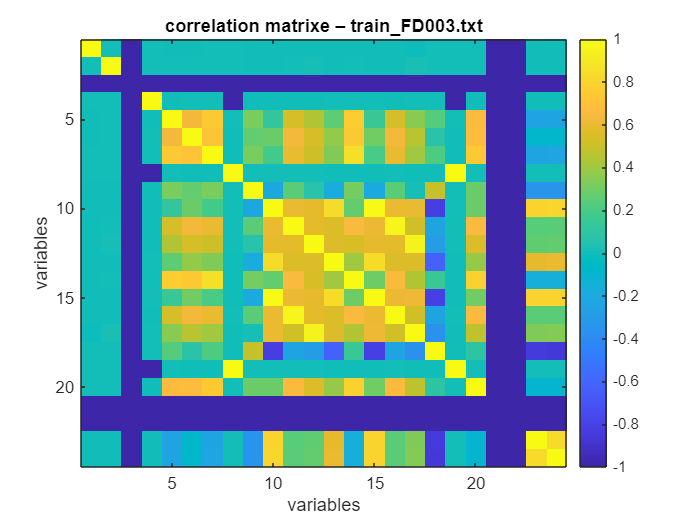

Variance explained by first 10 PCs:


   41.3774   26.3693    5.5818    5.5586    5.1302    4.3408    2.3984    1.8835    1.7029    1.3850



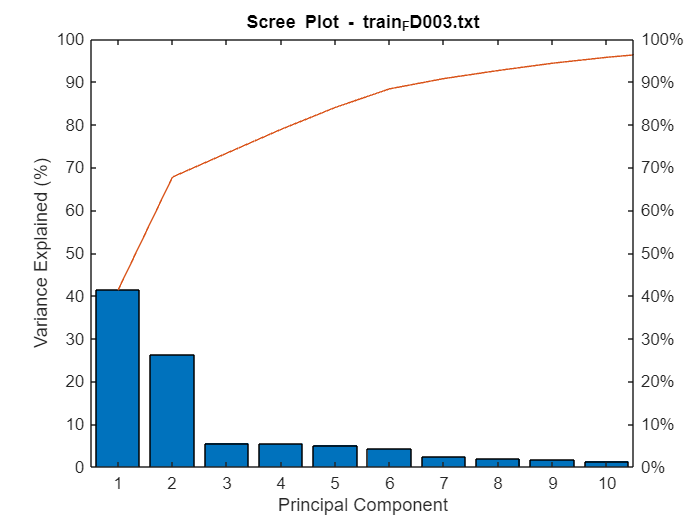

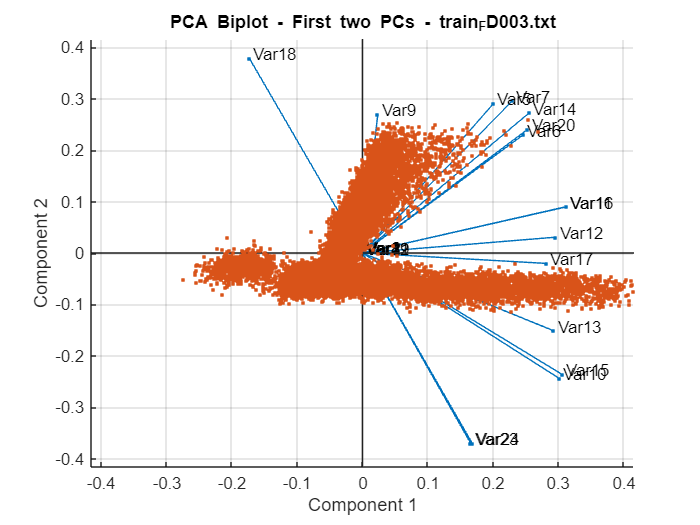

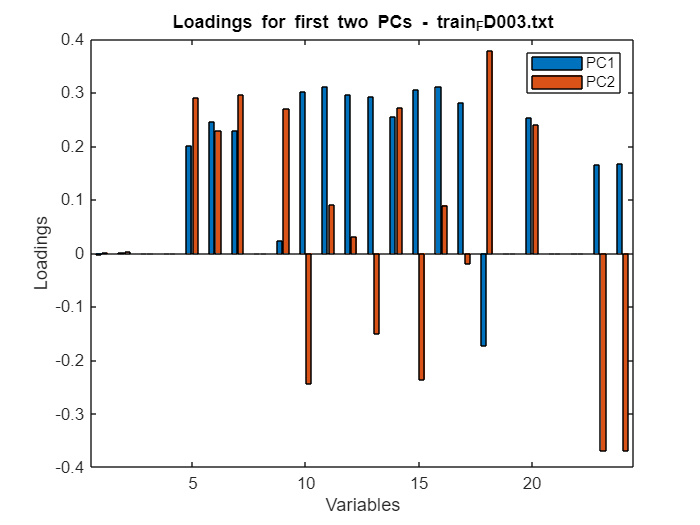

 Analysis dataset: train_FD004.txt


Matrice X: 61249 osservazioni (righe) × 24 variabili (colonne)


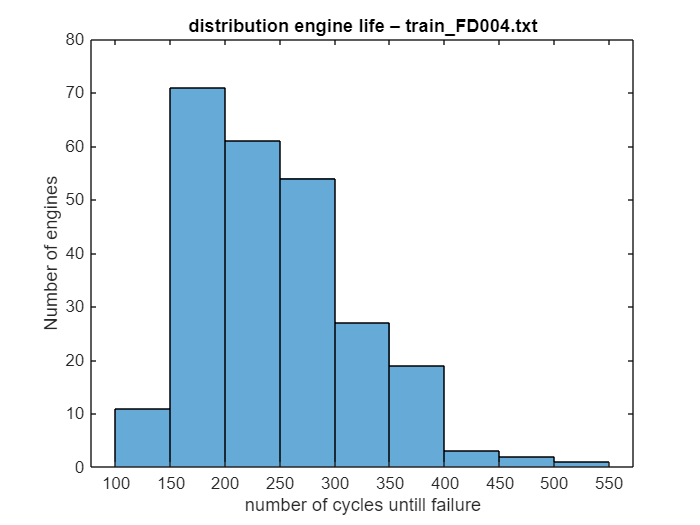

number of eninges: 249


average engine life (cycles): 245.98


no missin values.


no constant variables.


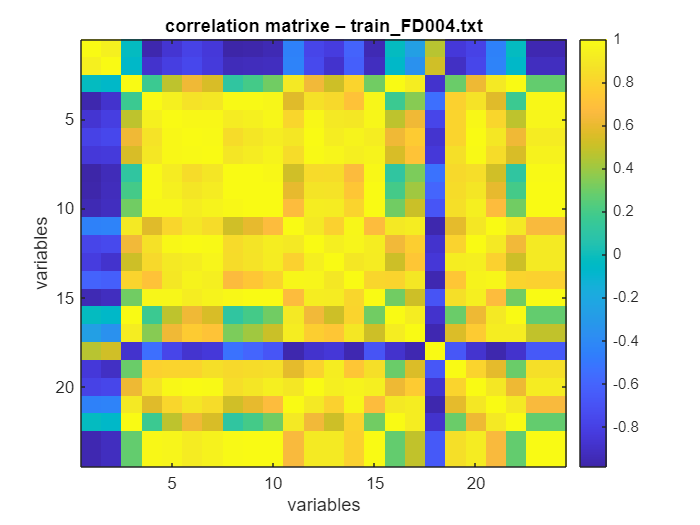

Variance explained by first 10 PCs:


   77.3578   19.9629    1.9862    0.3184    0.1702    0.0788    0.0647    0.0297    0.0133    0.0056



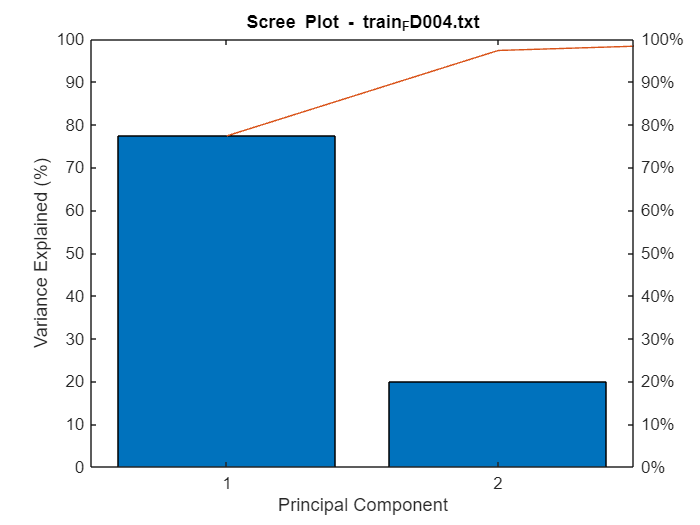

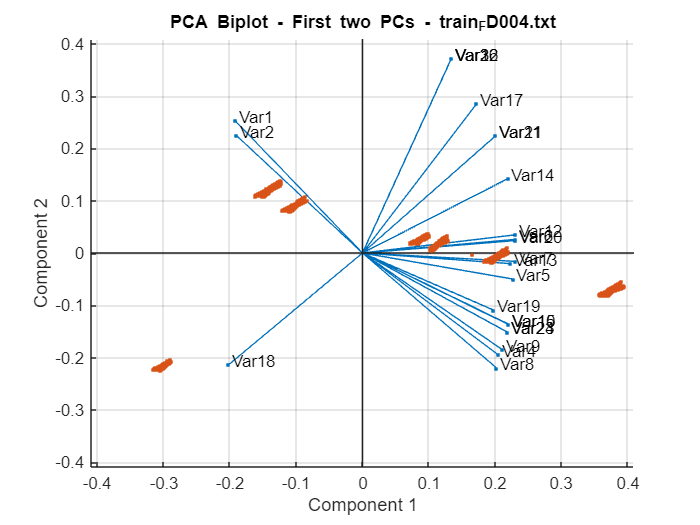

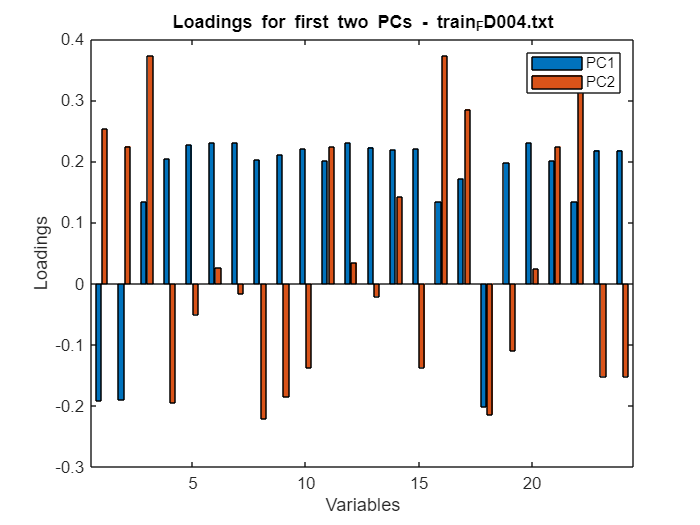


trainFiles = { ...
    'train_FD001.txt', ...
    'train_FD002.txt', ...
    'train_FD003.txt', ...
    'train_FD004.txt'};

% Loop on every dataset
for f = 1:numel(trainFiles)
    fprintf('\n==============================\n');
    fprintf(' Analysis dataset: %s\n', trainFiles{f});
    fprintf('==============================\n');
    
    trainData = readmatrix(trainFiles{f});
    
    [X_train, unit_train, cycle_train] = extractPredictors(trainData);
    
    uniqueUnits = unique(unit_train);
    nUnits = numel(uniqueUnits);
    cyclesPerUnit = zeros(nUnits,1);

    for i = 1:nUnits
        cyclesPerUnit(i) = sum(unit_train==uniqueUnits(i));
    end

    figure;
    histogram(cyclesPerUnit);
    xlabel('number of cycles untill failure');
    ylabel('Number of engines');
    title(sprintf('distribution engine life – %s', trainFiles{f}), 'Interpreter','none');

    fprintf('number of eninges: %d\n', nUnits);
    fprintf('average engine life (cycles): %.2f\n', mean(cyclesPerUnit));

    nMissing = sum(isnan(X_train),1);
    missingVars = find(nMissing>0);

    if ~isempty(missingVars)
        fprintf('Variables with missing values:\n');
        disp(missingVars);
    else
        fprintf('no missin values.\n');
    end

    varPerCol = var(X_train);
    constVars = find(varPerCol==0);

    if ~isempty(constVars)
        fprintf('constant variables:\n');
        disp(constVars);
    else
        fprintf('no constant variables.\n');
    end

    corrMatrix = corr(X_train);
    figure;
    imagesc(corrMatrix);
    colorbar;
    title(sprintf('correlation matrixe – %s', trainFiles{f}), 'Interpreter','none');
    xlabel('variables');
    ylabel('variables');

    % ============ PCA Exploratory Data Analysis ============
    nVar = size(X_train, 2);  % Get number of variables
    
    % Normalize the data to zero mean and unit variance before PCA
    X_norm = zscore(X_train);
    
    % Perform PCA
    [coeff, score, latent, tsquared, explained, mu] = pca(X_norm);
    
    % Display variance explained by first 10 PCs
    fprintf('Variance explained by first 10 PCs:\n');
    disp(explained(1:10)');
    
    % Scree plot - variance explained
    figure;
    pareto(explained);
    xlabel('Principal Component');
    ylabel('Variance Explained (%)');
    title(sprintf('Scree Plot - %s', trainFiles{f}));
    saveas(gcf, sprintf('PCA_ScreePlot_%s.png', trainFiles{f}(1:end-4)));

    % Biplot of first two principal components
    figure;
    biplot(coeff(:,1:2), 'Scores', score(:,1:2), ...
        'VarLabels', arrayfun(@(x) sprintf('Var%d', x), 1:nVar, 'UniformOutput', false));
    title(sprintf('PCA Biplot - First two PCs - %s', trainFiles{f}));
    saveas(gcf, sprintf('PCA_Biplot_%s.png', trainFiles{f}(1:end-4)));

    % Loading plot for first two principal components
    figure;
    bar(coeff(:,1:2));
    xlabel('Variables');
    ylabel('Loadings');
    legend({'PC1','PC2'});
    title(sprintf('Loadings for first two PCs - %s', trainFiles{f}));
    saveas(gcf, sprintf('PCA_Loadings_%s.png', trainFiles{f}(1:end-4)));
end

datasets = {'FD001', 'FD002', 'FD003', 'FD004'};
plotTypes = {'ScreePlot', 'Loadings', 'Biplot'};

for k = 1:length(plotTypes)
    fig = figure('Name', ['PCA ', plotTypes{k}, 's'], 'NumberTitle', 'off');
    for i = 1:length(datasets)
        subplot(2,2,i);
        filename = ['PCA_', plotTypes{k}, '_train_', datasets{i}, '.png'];
        img = imread(filename);
        imshow(img);
        title([plotTypes{k}, ' ', datasets{i}], 'Interpreter', 'none');
    end
    % Save figures
    saveas(fig, ['Combined_PCA_', plotTypes{k}, '.png']);
    close(fig);
end
